# MAIN PROGRAM

clc, close all, clear all

**Dataset structure:** Dataset contains 3D timeseries data type and each sample data is originally stored in separate file. There are 1000 separate matlab data files and each of the data file is ONE observation. An observation is a trajectory which is written in the air with the fingertip and the 3D location (x, y, z coordinates) of the fingertip during the process of writing ONE digit was recorded. There is an equal number of observations in each class (or digit) and there are 10 classes corresponding to 10 digits from 0 to 9. Depending on the time of the writing process, a trajectory can have more or less number of timesteps at which a new 3D location data is recorded. For example: If the owner of a trajectory writes quickly a digit, the data file can have less number of rows, which refers to the number to timesteps at which the location of his/her fingertip is recorded, than in case he/she writes it slowly. Each new timestep has equally fixed timeout at when a new record of location of fingertip is added. Unfortunately, the information about the timeout interval was not available. All data files have three columns corresponding to x, y and z cooridates of a fingertip and different number of rows corresponding to the number of timesteps which depend mainly on the amount of time it takes for the user to complete a trajectory. Thus, preprocessing data must be implemented in order to achieve consistent size of sample data which is then used in model training.

In order to avoid lengthening the main program, most of the operations of feature engineering were implemented in their own separate files or were defined as functions. That allowed better colaboration and team work.

## Step 1: Load all original 3D stroke data files into one cell array and create a column vector of classes

There are 1000 data files with file name's format as “stroke_[digit/class]_[sample number].mat”. For example: the file named "stroke_7_0012.mat" stores the 12th instances of digit 7.

The first step is to load all data files into a cell array (1*1000 cell array) with each sample data staying in one cell. An array of classes (1000*1 vector) are generated based on the order of the loaded files.

fprintf("Step 1: Data loading...");

Step 1: Data loading...

run data_loading.m;

*Results: raw_data.mat containing 2 variables (raw_data and data_class)*

- *A cell array named raw_data which contains 1000 cells in each which stays a matrix with 3 columns and a different number of rows.*

- *A column vector named data_class which contains classes of 1000 observations in a corresponding order of the cell array of observations (100 observations in each class and they are stored in an accending order).*

fprintf("Results: raw_data.mat")

Results: raw_data.mat

raw_data, data_class

raw_data = 1×1000 cell array
  Columns 1 through 586

    {32×3 double}    {34×3 double}    {220×3 double}    {76×3 double}    {52×3 double}    {50×3 double}    {84×3 double}    {80×3 double}    {39×3 double}    {35×3 double}    {32×3 double}    {22×3 double}    {53×3 double}    {49×3 double}    {41×3 double}    {47×3 double}    {115×3 double}    {46×3 double}    {36×3 double}    {22×3 double}    {51×3 double}    {55×3 double}    {76×3 double}    {39×3 double}    {23×3 double}    {41×3 double}    {47×3 double}    {95×3 double}    {40×3 double}    {65×3 double}    {33×3 double}    {113×3 double}    {36×3 double}    {33×3 double}    {52×3 double}    {41×3 double}    {37×3 double}    {34×3 double}    {54×3 double}    {35×3 double}    {35×3 double}    {48×3 double}    {88×3 double}    {44×3 double}    {36×3 double}    {106×3 double}    {49×3 double}    {28×3 double}    {102×3 double}    {80×3 double}    {38×3 double}    {57×3 double}    {38×3 double}    {38×3 double}    {39×3 double}    {5

data_class =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


## Step 2: Preprocess raw_data and transform it from cell type to matrix type

In the second step, the "raw_data" cell array outputted from the previous step enters the preprocessing phase which is one of the most important steps to achieve a clean and well-structured data matrix for any training and testing phases. During this stage, there are three substeps namely data normalization, feature extraction and data reallocation. The needs of those substeps are revealed below. Three separate functions corresponding to three substeps are defined as resources for the implementation of the preprocessing procedure which is built in matlab file *data_preprocessing.m*.

load raw_data.mat

**The need of Data Normalization:** Due to the fact that a user can make a trajectory from any location as long as that location can still been seen in the covered area of the Leap Motion camera, a trajectory can be big or small. That causes a problem with data samples which each has different scale. Hence, data scalling is performed in order to bring all sample data onto the same scale, since in this project, we are not interested in the recognization of the size of the trajectories, but rather in the digits that the trajectories is revealed, or in other words, the shape of the trajectories. 

=> A function called data_normalization has been defined in matlab file *data_normalization.m* to facilitate the performance of Min-Max scaling on the "raw_data" (type "help data_normalization" in command window for definition of the function).

**The need of Data Extraction: **As explained about the dataset structure, there is an inconsistency in the size of each sample data due to the different number of timesteps recorded by the camera during the writing process of trajectories. That inconsistency had prevented us from moving forwards because it is impossible to perform matrix computing with inconsistent size. The below code snippet reveals the average, maximum and minimum number of rows occurred in this dataset.

fprintf("Step 2 (pre-step): Sample data matrix size inspecting and decision making...");

Step 2 (pre-step): Sample data matrix size inspecting and decision making...

sample_size = [];
for i = 1:length(raw_data)
    sample_size = [sample_size size(raw_data{1,i},1)];
end

fprintf('The average of number of rows of all observations is %d.\n', mean(sample_size));

The average of number of rows of all observations is 5.525000e+01.


fprintf('The maximum of number of rows of all observations is %d.\n', max(sample_size));

The maximum of number of rows of all observations is 222.


fprintf('The minimum of number of rows of all observations is %d.\n', min(sample_size));

The minimum of number of rows of all observations is 19.


fprintf("=> Decision: Extract only 19 timesteps in each observation to achieve consistency in matrix size. " + ...
    "\nInformation about the extraction process can be consulted from feature_extraction.m");

=> Decision: Extract only 19 timesteps in each observation to achieve consistency in matrix size. 
Information about the extraction process can be consulted from feature_extraction.m

To overcome the inconsistency, there are at least three options in order to obtain a consistent number of rows in each sample data: 

- The first option is to choose the most number of rows occurred in the dataset and consider it as the standard number of rows that all samples must have, then filling missing data or upsampling must be performed on each sample. For example: If there is sample with 222 rows which is the maximum, all other samples that have less than that number of rows will have to go through a process of upsampling to have the same number of rows. Strategy to perform the filling is not simple.

- The second option is to choose the least number of rows occurred in the dataset and consider it as the standard number of rows that all samples must have, then data extraction must be performed on each sample to keep only such number of rows and discard all the other rows. For example: If there is sample with 19 rows which is the minimum, all other samples that have more than that number of rows will have to go through a process of data extraction to have the same number of rows. Strategy to perform the filling is not simple.

- The third option is a mixed strategy to the two ealier mentioned options. It means that instead of choosing the maximum or minimum, any other number in between can be chosen. It is obvious that with this option, both upsampling and extraction can be performed to achieve a consistent matrix.

**=> Decision:** We decided to go with the second option after considering the complexity of the task and the burden of having a huge number of features. Firstly, we can cross the third option out due to extra complexity to the work with no exceptionally addition to the performance. The first option may seem promising, but if the maximum number is chosen, the size of all other 999 sample data matrix will hugely increase. Additionally, as the new location data would be generated with algorithms instead of real data, there is no guarantee of better performance of upsampling compared to extracting real data from the real set. Furthermore, in the later step, data cells are transformed into ONE matrix and each x, y, z coordinate of each timestep is considered as an independent feature, considering that, obtaining a dataset of 3 columns multiplying by 222 rows of each sample resulting in a matrix of 1000 rows corresponding 1000 samples and 666 features is not ideal. Therefore, the second option is chosen and that facilitate the use of real data timesteps extracted from the normalized original sample data and the standard number of rows is 19.

=>  A function called feature_extraction has been defined in matlab file *feature_extraction.m* to facilitate the performance of extraction of number of rows on the normalized data to achieve the provided standard number of rows (type "help feature_extraction" in command window for definition of the function). This sub-step was implemented carefully to ensure no loss in critical curve of any number

**The need of data_reallocation:** Until this stage, the dataset had still been in form of cell array, meaning that even though the sample data matrices are now normalized and consistent in size of 3 columns * 19 rows, they are still in each of their own separate cells. To ease the computing and model training, we decided to apply a simple transformation step, so that all 1000 data samples could be stored in ONE single matrix. It is very simple that we considered each coordinate of one sample as one independent feature. For example, each sample, which has 3 columns representing x, y, z coordinates and 19 rows representing timesteps, can be transformed into one single row vector with 3*19 (=57) elements which are x1, y1, z1, x2, y2, z2,..., x19, y19, z19.

=> A function called data_reallocation has been defined in matlab file *data_reallocation.m* to facilitate the performance of the transformation as explained thoroughly above (type "help data_reallocation" in command window for definition of the function).

All three mentioned substeps are implemented in the matlab file named *data_preprocessing.m* which firstly loaded the *raw_data.mat*, performed the three substeps on the "raw_data" cell array. After normalization, extraction and reallocation, the dataset is stored in the variable named "data". The vector "data_class" is left untouched. The two variables "data" and "data_class" are saved into the *data.mat* matlab data file.

run data_preprocessing.m;
fprintf("Step 2: Data preprocessing...")

Step 2: Data preprocessing...

fprintf("Substep 2.1: Data normalizing...");

Substep 2.1: Data normalizing...

fprintf("Substep 2.2: Feature extracting...");

Substep 2.2: Feature extracting...

fprintf("Substep 2.3: Data reallocating...");

Substep 2.3: Data reallocating...

*Results: data.mat containing 2 variables (data and data_class)*

- *Data has first been normalized to bring all trajectories to the same scale, because we are not interested in different size of the stroke but the shape of it. *

- *Then, the data has been extracted to keep only necessary 3D location data, which includes only 19 timesteps in order to keep the data matrix consistent, because originally each stroke data has different number of timesteps based on how fast the trajectories had been created. *

- *Lastly, the dataset which had been in cell array type, has been reallocated into a resulting matrix with size of 1000 rows (number of samples) and 57 columns (number of features).*

fprintf("=> Results: data.mat")

=> Results: data.mat

data, data_class

data =     0.4839    0.9734    0.7498    0.4803    0.9724    0.7285    0.4682    0.9719    0.6716    0.4376    0.9666    0.5966    0.3852    0.9548    0.6004    0.3053    0.9331    0.5464    0.2060    0.8840    0.6513    0.0251    0.6677    0.6519    0.0122    0.4294    0.8483    0.1112    0.2103    1.0000    0.3283    0.0362    0.9284    0.6333         0    0.6000    0.8986    0.1055    0.0547    1.0000    0.3407    0.0162    0.8809    0.6213    0.3244    0.6949    0.8327    0.4994    0.4662    0.9673
    0.5026    0.9476    0.5530    0.4930    0.9544    0.5804    0.4805    0.9612    0.6305    0.4578    0.9670    0.6726    0.4240    0.9691    0.7054    0.2992    0.9297    0.6811    0.1100    0.8070    0.4981    0.0094    0.5760         0    0.0089    0.3938    0.1542    0.1221    0.1853    0.4425    0.3556    0.0360    0.6962    0.5438         0    0.8413    0.8589    0.0520    0.9283    0.9878    0.2352    0.8403    0.9870    0.4591    0.8037    0.8461    0.6943    0.6492    0.6559  

data_class =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


*=> This step allowed us to transform inconsistent 3D timeseries data into a more familiar form of ONE SINGLE MATRIX with samples on rows and features on columns. Now, the data is ready for any further usage.*

## Step 3: Split data for training (90%) and testing (10%)

In order to assure the unbiased assessment of the generalization performance of the final model, it is important to keep a part of the data set (10%) only for testing purpose. This test data shall never be used until the final model has been completely trained. The rest of the dataset (90%) can enter the training phases. Therefore, data splitting shall be performed in this step on the data.mat data file outputted from the previous step.

load data.mat

There is Matlab's built-in function cvpartition whose main functionality is to assist in splitting the data with specific method. With the function, dataset divisions are usually generated randomly according to a target variable. However, Matlab's function usually produces nonstratified partitions if no additional options specified, meaning that the proportions of the target variable among the different splits can differ, especially in the case of small datasets. This means that we are training and evaluating in heterogeneous subgroups, which will lead to prediction errors. It does not seem to be an ideal solution for our not too big multi-class dataset with only 100 samples in each class.

The solution is simple: **stratified sampling**. This technique consists of forcing the distribution of the target variable(s) among the different splits to be the same. This small change will result in training on the same population in which it is being evaluated, achieving better predictions.

=> A function called data_Holdout_splitting has been defined in matlab file *data_Holdout_splitting.m* to achieve the advantages of stratification in holdout partitioning (type "help data_Holdout_splitting" in command window for definition of the function). Note that, Matlab's cvpartition offers option to set stratification to true to perform the exact same functionality of this defined function. Therefore, this function is defined mainly for the sake of learning.

Its main responsibility is to ensure that the split train set and test set have same proportion of each class. For example: our data set has 1000 samples of 10 classes, after 90/10 hold out splitting with our own defined function, we desire to have 900 samples in the train set and 100 samples in the test set, and as much important as that, we expect to have each 10% of the sets is from one class, so that there are exactly 90 samples of class 0 in the train data and 10 samples of the same class in the test data. By that, we can avoid imbalance of any class used in training and testing.

=> A function called data_Holdout_splitting has been defined in matlab file *data_Holdout_splitting.m *(type "help data_Holdout_splitting" in command window for definition of the function).

By specifying the TestDataProportion at 0.1, we can do 90/10 splitting on the whole dataset so that 90% of the whole dataset is stored in train set and 10% is in test set.

fprintf("Step 3: Data 90/10 splitting...");

Step 3: Data 90/10 splitting...

TestDataProportion = 0.1;
[traindata, trainclass, testdata, testclass] = data_Holdout_splitting(data, data_class, TestDataProportion);

The train set ("traindata" and "trainclass") and test set ("testdata" and "testclass") are stored in the *split_data.mat.*

save split_data.mat traindata trainclass testdata testclass;

fprintf("=> Results: split_data.mat");

=> Results: split_data.mat

traindata, trainclass

traindata =     0.4312    0.9455    0.2795    0.4390    0.9494    0.3105    0.4477    0.9609    0.3252    0.2886    0.9553    0.1505    0.1250    0.8061    0.1298    0.0310    0.6196    0.3002    0.0002    0.4186    0.4673    0.0124    0.2669    0.6066    0.0865    0.1333    0.7463    0.2135    0.0654    0.8587    0.4139    0.0142    0.9537    0.6546    0.0142    0.9735    0.8505    0.1144    0.9070    0.9731    0.2714    0.6760    0.9647    0.4879    0.4806    0.8322    0.7090    0.4102    0.5734    0.8874
    0.8596    0.8199    0.0273    0.8582    0.8279    0.0196    0.8576    0.8310    0.0271    0.8511    0.8410    0.0704    0.8217    0.8461    0.1257    0.6464    0.8334    0.1891    0.5293    0.8070    0.2398    0.2760    0.6828    0.4675    0.1604    0.6150    0.5469    0.0237    0.4615    0.3709         0    0.3392    0.3271    0.1905    0.1128    0.2738    0.5670    0.0006    0.2682    0.9039    0.0997    0.2228    1.0000    0.3756    0.1605    0.9032    0.7186    0.4514    0.6

trainclass =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


testdata, testclass

testdata =     0.6670    0.8230    0.1207    0.6793    0.8298    0.1319    0.6940    0.8424    0.0680    0.7003    0.8501    0.0755    0.6916    0.8663    0.0797    0.5779    0.8745    0.0158    0.4646    0.8436         0    0.2347    0.7261    0.0721    0.1345    0.6425    0.1529    0.0112    0.4336    0.4770         0    0.3243    0.6391    0.1426    0.0757    0.9794    0.5616    0.0085    0.7943    0.9239    0.2254    0.3897    1.0000    0.4857    0.1685    0.8079    0.8171    0.1908    0.5060    0.9682
    0.5615    0.9508    0.2417    0.5909    0.9781    0.2465    0.5978    0.9995    0.2584    0.4714    0.9603    0.1575    0.2939    0.8898    0.1454    0.0665    0.6379    0.5611         0    0.4088    0.6388    0.0363    0.2131    0.8275    0.1765    0.0657    0.9578    0.4054    0.0127    0.9610    0.6562    0.0315    0.8183    0.8457    0.1181    0.5824    0.9824    0.2692    0.3391    0.9792    0.4681    0.2127    0.8782    0.6317    0.2442    0.6787    0.7493    0.2492    0.44

testclass =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Visualization of distribution of observations belonging to each class in train set and test set

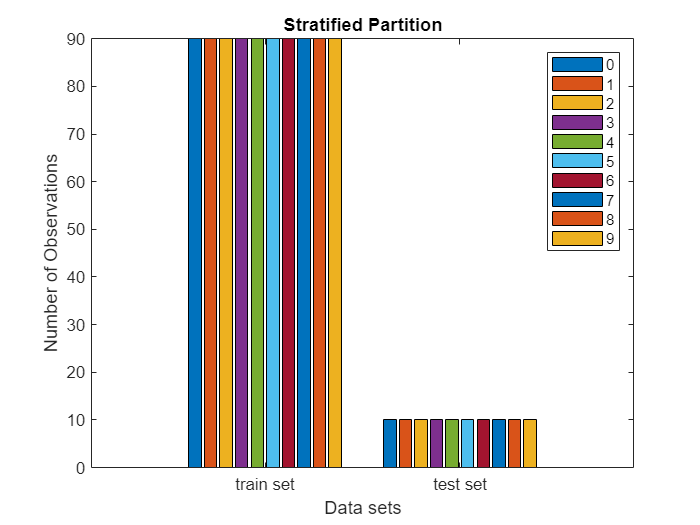

ntrainCounts = countcats(categorical(trainclass)); % Number of train set observations in each class
ntestCounts = countcats(categorical(testclass)); % Number of test set observations in each class
nData(1,:) = ntrainCounts';
nData(2,:) = ntestCounts';

xticks = categorical({'train set','test set'});
xticks = reordercats(xticks,{'train set','test set'});
bar(xticks,nData);
xlabel('Data sets');
ylabel('Number of Observations');
title('Stratified Partition');
legend(categories(categorical(trainclass)));


fprintf("=> Results: train set has 900 samples, test set has 100 samples. The distribution of the samples in all sets are equal.");

=> Results: train set has 900 samples, test set has 100 samples. The distribution of the samples in all sets are equal.

*Results: 900 samples enters training phases and 100 samples enters testing phase after the final model is available. The distribution of samples in all sets are equal.*

## Step 4.1: Perform PCA on train data (keep 98%)

As mentioned earlier, our data matrix has 57 features which motivate us to perform Principal Component Analysis (PCA) and the main purpose is feature reduction.

=> A function called pca_implementation has been defined in matlab file *pca_implementation.m *(type "help pca_implementation" in command window for definition of the function).

The function takes two inputs, one is the train data and the other is the threshold of the explained total variance. The threshold is used to select the top principal components. In this case, we chose to set the threshold as 98%.

fprintf("Step 4.1: PCA performing on train data...")

Step 4.1: PCA performing on train data...

In order to achieve 98 percent of total variance, 22 first components was selected.

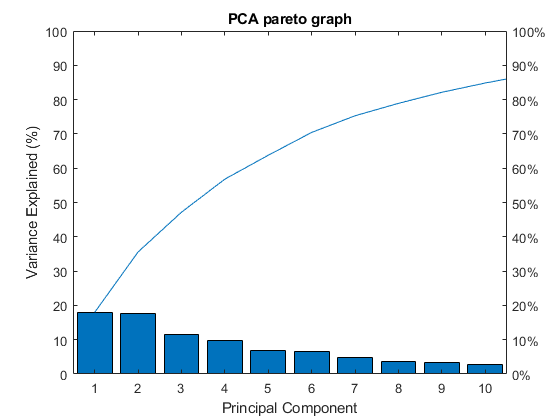

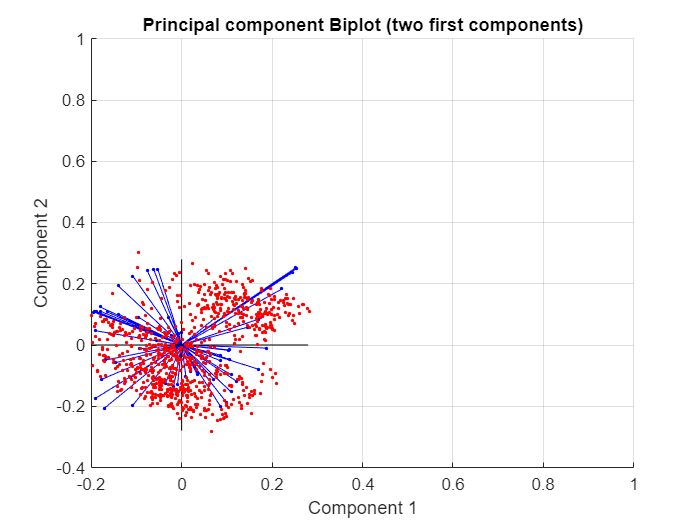

[coeff, trainX, scores, explained, mu, toKeepComponentsIdx] = pca_implementation(traindata, 98);

save pca_output.mat coeff mu toKeepComponentsIdx scores

fprintf("=> Results: pca_output.mat stores PCA configuration and trainX");

=> Results: pca_output.mat stores PCA configuration and trainX

trainX

trainX =     1.7746    0.9759   -0.3758   -0.1336    0.2006    0.1471   -0.5830    0.2722    0.2679    0.0669    0.1745   -0.4037    0.0908   -0.1282   -0.0790    0.3152    0.0947   -0.0568   -0.1996   -0.1300    0.1685    0.0124
    0.7466    1.1769    1.0977   -0.2291   -0.4159   -0.0521   -0.5140   -0.8282   -0.0719   -0.4547    0.0202   -0.0162    0.1884    0.6693   -0.1846    0.6189   -0.0357    0.0458   -0.1409    0.1094    0.0971    0.0477
    0.5816    1.3927   -0.4163    0.2984    0.8263   -0.5834    0.7117   -0.2594   -0.2250   -0.4576   -0.6601    0.5097   -0.3779   -0.7098    0.1902    0.3745    0.4067   -0.1657    0.1441    0.1826   -0.1338    0.1837
    1.6822    0.9459    0.0519    0.0833    0.3773   -0.0529   -0.3457    0.3369    0.6962   -0.2736   -0.1998    0.3293    0.3146    0.2810    0.0605   -0.2613   -0.2086    0.0622    0.2311    0.0444   -0.0716    0.0140
    2.0899    0.8203   -0.3827   -0.0653    0.0889   -0.3936   -0.4491    0.6301   -0.5425    0.0952   -0.3

*Results: We performed PCA and thereby, reducing the dataset from having 57 features to 22 features while keeping the information loss less than 2%. We use 22 (as outputted in the variable "toKeepComponentsIdx") components (stored in trainX) for training our machine learning models.*

## Step 4.2: Transform the test set by using the PCA obtained from the train set

A function called pca_transformation has been defined in matlab file pca_transformation.m (type "help pca_transformation" in command window for definition of the function). The function aims at obtaining the principal component scores of the test data set by subtracting `mu` from testdata and multiplying by `coeff`. Only the scores for the first 22 components are necessary, so use the first 22 coefficients coeff(:,toKeepComponentsIdx).

fprintf("Step 4.2: Test data transforming using PCA configuration...");

Step 4.2: Test data transforming using PCA configuration...

testX = pca_tranformation(testdata, coeff, mu, toKeepComponentsIdx);

fprintf("=> Results: testX");

=> Results: testX

testX

testX =     1.1481    1.2346    0.6048   -0.3622   -0.9597    0.0502   -0.5758    0.1064   -0.6875    0.0674    0.1355    0.1007    0.1183    0.1766    0.1354    0.5613   -0.0902    0.1459   -0.0771    0.0067    0.0870    0.0686
    1.3455    1.3189   -0.6236    0.2128    0.5133   -0.4073   -0.4137   -0.2666    0.0746   -0.1505   -0.0797   -0.5803    0.1168   -0.0553   -0.1664    0.1018    0.1082   -0.0483   -0.1782   -0.0925    0.1308    0.1062
    0.7184    0.8950   -0.7826    0.3285    1.2341   -0.0687    1.0898   -0.3836    0.3352    0.3615   -0.8977    0.2090    0.4141    0.0042    0.1114    0.1596   -0.0268   -0.1792    0.3134    0.1081    0.3084   -0.0168
    1.9268    0.7822   -0.1309    0.0020    0.6631   -0.6175    0.2106   -0.3479   -0.1463    0.1632    0.1933   -0.1776   -0.1501    0.0312   -0.1684    0.0960   -0.0323    0.0709    0.0578   -0.0956    0.0328   -0.1060
    1.2076    1.1342    0.5416    0.1909    0.6090    0.3828    0.1058    0.0855   -0.0721    0.1795    0.49

*Results: testX is the transformed test data and it can be used for testing purpose.*

## Step 5.1: Create dummy variable of class to assist logistics model training

Because our class is 0-9, we plus 1 to each element to obtain class of 1-10 to suit the Matlab built-in function dummyvar.

This step concerns only the use case of training logistics model due to the fact that this is a multi-class problem.

fprintf("Step 5.1: Dummy variable for class vectors creating...");

Step 5.1: Dummy variable for class vectors creating...


trainclass_dummy = dummyvar(trainclass+ones(size(trainclass)));
testclass_dummy = dummyvar(testclass+ones(size(testclass)));

## Step 5.2: Save train data and test data

fprintf("Step 5.2: Train set and test set saving...");

Step 5.2: Train set and test set saving...


save train_data.mat trainX trainclass trainclass_dummy
save test_data.mat testX testclass testclass_dummy

=> The 5 steps above has been done in order to achieve the train_data.mat and test_data.mat. 

fprintf("=> Results: train_data.mat");

=> Results: train_data.mat


trainX, trainclass, trainclass_dummy

trainX =     1.7746    0.9759   -0.3758   -0.1336    0.2006    0.1471   -0.5830    0.2722    0.2679    0.0669    0.1745   -0.4037    0.0908   -0.1282   -0.0790    0.3152    0.0947   -0.0568   -0.1996   -0.1300    0.1685    0.0124
    0.7466    1.1769    1.0977   -0.2291   -0.4159   -0.0521   -0.5140   -0.8282   -0.0719   -0.4547    0.0202   -0.0162    0.1884    0.6693   -0.1846    0.6189   -0.0357    0.0458   -0.1409    0.1094    0.0971    0.0477
    0.5816    1.3927   -0.4163    0.2984    0.8263   -0.5834    0.7117   -0.2594   -0.2250   -0.4576   -0.6601    0.5097   -0.3779   -0.7098    0.1902    0.3745    0.4067   -0.1657    0.1441    0.1826   -0.1338    0.1837
    1.6822    0.9459    0.0519    0.0833    0.3773   -0.0529   -0.3457    0.3369    0.6962   -0.2736   -0.1998    0.3293    0.3146    0.2810    0.0605   -0.2613   -0.2086    0.0622    0.2311    0.0444   -0.0716    0.0140
    2.0899    0.8203   -0.3827   -0.0653    0.0889   -0.3936   -0.4491    0.6301   -0.5425    0.0952   -0.3

trainclass =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


trainclass_dummy =      1     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0



fprintf("=> Results: test_data.mat");

=> Results: test_data.mat


testX, testclass, testclass_dummy

testX =     1.1481    1.2346    0.6048   -0.3622   -0.9597    0.0502   -0.5758    0.1064   -0.6875    0.0674    0.1355    0.1007    0.1183    0.1766    0.1354    0.5613   -0.0902    0.1459   -0.0771    0.0067    0.0870    0.0686
    1.3455    1.3189   -0.6236    0.2128    0.5133   -0.4073   -0.4137   -0.2666    0.0746   -0.1505   -0.0797   -0.5803    0.1168   -0.0553   -0.1664    0.1018    0.1082   -0.0483   -0.1782   -0.0925    0.1308    0.1062
    0.7184    0.8950   -0.7826    0.3285    1.2341   -0.0687    1.0898   -0.3836    0.3352    0.3615   -0.8977    0.2090    0.4141    0.0042    0.1114    0.1596   -0.0268   -0.1792    0.3134    0.1081    0.3084   -0.0168
    1.9268    0.7822   -0.1309    0.0020    0.6631   -0.6175    0.2106   -0.3479   -0.1463    0.1632    0.1933   -0.1776   -0.1501    0.0312   -0.1684    0.0960   -0.0323    0.0709    0.0578   -0.0956    0.0328   -0.1060
    1.2076    1.1342    0.5416    0.1909    0.6090    0.3828    0.1058    0.0855   -0.0721    0.1795    0.49

testclass =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


testclass_dummy =      1     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0


=> The test_data.mat shall be kept untouched until the training of the final model has been completed. It is used only at the end of the program to assess the performance of final model.

=> The train_data.mat are now used for training multiple models and cross-validating them to perform hyperparameter tuning and final model selection.

## Step 6: Partitioning for cross validation

This step does partitioning on the train set stored in train_data.mat to prepare for training and cross validation. Stratification is specified in Kfold partitioning when using Matlab's built-in cvpartition function.

We chose to train multiple models and perform cross validation with 4 folds.

k = 4;
fprintf("Step 6: Kfold partitioning with k = %d...",k);

Step 6: Kfold partitioning with k = 4...


rng('default') % For reproducibility
cvp = cvpartition(trainclass,'KFold',k,'Stratify',true) 

cvp = K-fold cross validation partition
   NumObservations: 900
       NumTestSets: 4
         TrainSize: 675  675  675  675
          TestSize: 225  225  225  225

Results from stratified partitioning can be indicated with bar graph showing count of each class in each fold.

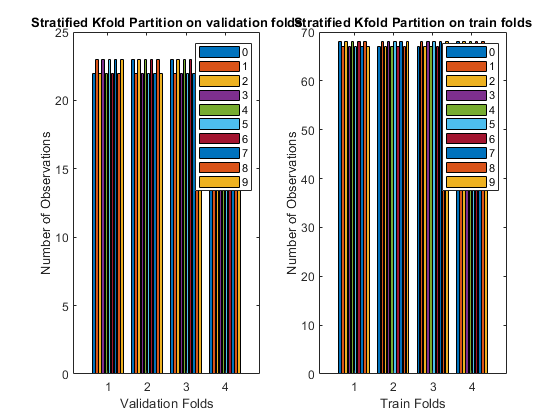

classes = 0:9;
numClasses = length(classes);
numFolds = cvp.NumTestSets;

% Visualization on test folds
nvalfold = zeros(numFolds,numClasses);
for i = 1:numFolds
    valfoldClasses = trainclass(cvp.test(i));
    nvalfoldCounts = countcats(categorical(valfoldClasses)); % Number of test set observations in each class
    nvalfold(i,:) = nvalfoldCounts';
end

xvalfoldticks = categorical(cellstr(num2str((1:k)')));
subplot(1,2,1)
bar(xvalfoldticks,nvalfold);
xlabel('Validation Folds')
ylabel('Number of Observations')
title('Stratified Kfold Partition on validation folds')
legend(categories(categorical(trainclass)));

% Visualization on train folds
ntrainfold = zeros(numFolds,numClasses);
for i = 1:numFolds
    trainfoldClasses = trainclass(cvp.training(i));
    ntrainfoldCounts = countcats(categorical(trainfoldClasses)); % Number of test set observations in each class
    ntrainfold(i,:) = ntrainfoldCounts';
end

xtrainfoldticks = categorical(cellstr(num2str((1:k)')));
subplot(1,2,2)
bar(xtrainfoldticks,ntrainfold);
xlabel('Train Folds')
ylabel('Number of Observations')
title('Stratified Kfold Partition on train folds')
legend(categories(categorical(trainclass)));


fprintf("Matlab's cvpartition has well done the stratified kfold partition job. \n" + ...
    "The distribution of samples of different classes is similar in each fold. \n" + ...
    "It is not perfectly the same due to the fact that the number of samples in each fold is not even.")

Matlab's cvpartition has well done the stratified kfold partition job. 
The distribution of samples of different classes is similar in each fold. 
It is not perfectly the same due to the fact that the number of samples in each fold is not even.


fprintf("This kfold partition cvp is used in further training.")

This kfold partition cvp is used in further training.

Save the kfold partitions for further use in model training and hyperparameter tuning

save cvp.mat cvp

## Step 7: Train Decision Tree Classification Models

Decison tree algorithm tends to overfit. Therefore, it is essential to apply some methods to avoid that situation. In this case, we decided to train two different models with different types of restrictions such as minleafnode and maxsplit. The built-in Matlab function "fitctree" can also be used for multi-class classification task. As a result, it is used to train the two below decision tree models. 

First, Load train data and created kfold partition for training.

fprintf("Step 7: Classification tree models training...");

Step 7: Classification tree models training...

% load training data and created cvp parition for model training
load train_data.mat
load cvp.mat

Set the random distribution generator to default for reproducibility.

rng('default') % For reproducbility

**7.1  Train decison tree classification model with minleafnode restriction**

After experimenting with different configurations for the minimum number of samples required at a leaf node, we decided to go with the value 3 instead of other values to avoid both underfitting and overfitting. 

Therefore, the first classification tree model is trained with the minimum 3 samples required at a leaf node by using the function “fitctree”, calculate the misclassification error by using the function “kfoldLoss” and simply compute the accuracy of the model by taking 1 – the misclassification error.

minleafnode = 3;

% Train model
mdltree_minleafnode = fitctree(trainX,trainclass,'MinLeafSize',minleafnode,'CVPartition', cvp);
[Ypred_tree_minleafnode, Posterior_tree_minleafnode]  = kfoldPredict(mdltree_minleafnode);
error_tree_minleafnode = kfoldLoss(mdltree_minleafnode);
accuracy_tree_minleafnode = 1-error_tree_minleafnode;

fprintf("Classification tree model with minimum %d samples required at a leaf node\n" + ...
    "=> Accuracy of %5.2f%%\n", minleafnode, accuracy_tree_minleafnode*100);

Classification tree model with minimum 3 samples required at a leaf node
=> Accuracy of 76.44%


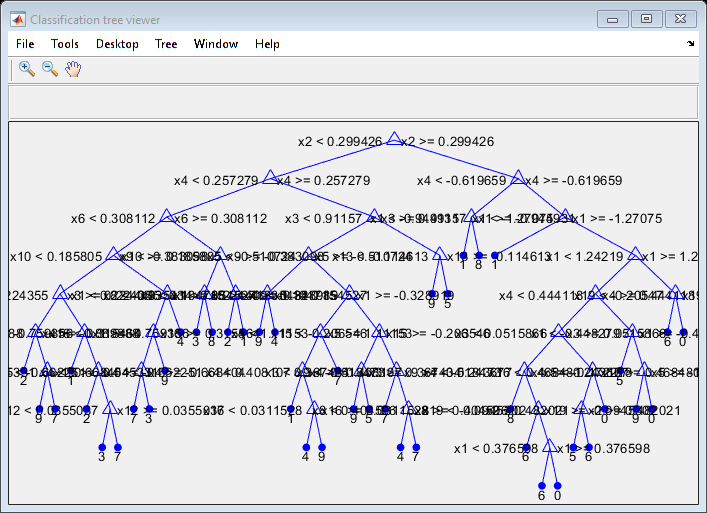


view(mdltree_minleafnode.Trained{1},'Mode','Graph');

**7.2  Train decison tree classification model with maxsplits restriction**

After experimenting with different configurations for the maximum number of splits, we decided to go with the value 30 instead of other values to avoid both underfitting and overfitting. 

Therefore, the second classification tree model is trained with the maximum 30 splits. The same training procedure is implemented here.

maxsplits = 30;

% Train model
mdltree_maxsplits = fitctree(trainX,trainclass,'MaxNumSplits',maxsplits,'CVPartition', cvp);
[Ypred_tree_maxsplits, Posterior_tree_maxsplits] = kfoldPredict(mdltree_maxsplits);
error_tree_maxsplits = kfoldLoss(mdltree_maxsplits);
accuracy_tree_maxsplits = 1-error_tree_maxsplits;

fprintf("Classification tree model with maximum %d splits\n" + ...
    "=> Accuracy of %5.2f%%\n", maxsplits, accuracy_tree_maxsplits*100);

Classification tree model with maximum 30 splits
=> Accuracy of 71.33%


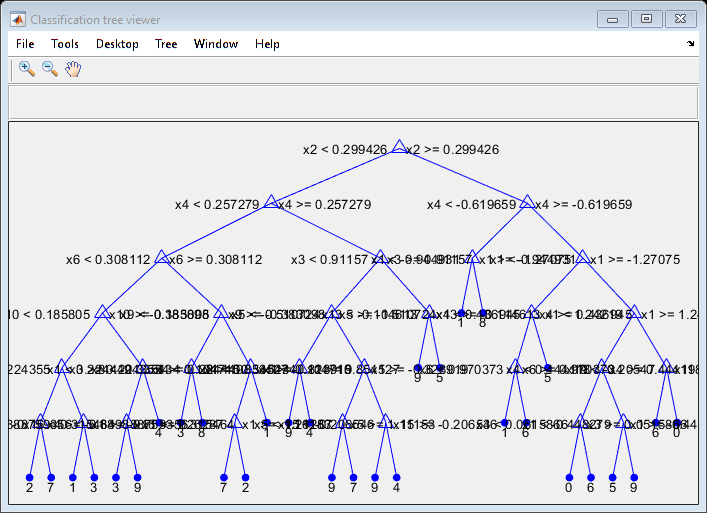


view(mdltree_maxsplits.Trained{1},'Mode','Graph');

**From my technical point of view, the decison tree classification model with minLeafnode restriction is better based on the comparison of accuracy between these 2 models.**

## Step 8: Train Support Vector Machine Classification Models

In this step, we will train 4 support vector machine models with different kernel functions and see how they perform. Due to the fact that, we have multi-class problem, therefore, the "fitcecoc" function was chose to train diffrent SVM models. For each trained model, the accuracy is computed and recorded to support the final model selection. A summary of all trained models and their performance can be found from the report.

fprintf("Step 8: Support Vector Machine models training...");

Step 8: Support Vector Machine models training...

% Load training data and created k-fold partition
load train_data.mat
load cvp.mat

Set the random distribution generator to default for reproducibility.

rng('default') % For reproducbility

**8.1 Kernel function: polynomial (Accuracy: 94.89%)**

The first SVM model is trained with Polynomial kernel function.  Polynomial kernel represents the similarity of vectors in the training set of data in a feature space over polynomials of the original variables used in the kernel.

The whole process of training the SVM model with polynomial Kernel function can be found below:

Firstly, an SVM template was created, all the predictors were standardized and using “polynomial” for Kernel function. Secondly, the function “fitcecoc” was used to train the SVM model and the function “crossval” was used to cross-validate the model based on the loaded partition cvp. In this case, k is 4. After that, the function “kfoldLoss” was used to compute the misclassification error and finally, the accuracy was computed by taking 1 - the misclassification error.

% KernelFunction: polynomial
t_1 = templateSVM('Standardize',true,'KernelFunction','polynomial','KernelScale','auto');
mdlSVM_Polynomial = fitcecoc(trainX,trainclass,'Learners',t_1,'FitPosterior',true,'ClassNames',{'0','1','2','3','4','5','6','7','8','9'});
CVmdlSVM_Polynomial = crossval(mdlSVM_Polynomial, 'CVPartition', cvp);
error_SVM_Polynomial = kfoldLoss(CVmdlSVM_Polynomial);
accuracy_SVM_Polynomial = 1 - error_SVM_Polynomial;

fprintf("Support Vector Machine model with Polynomial kernel function\n" + ...
    "=> Accuracy %5.2f%%\n", accuracy_SVM_Polynomial*100);

Support Vector Machine model with Polynomial kernel function
=> Accuracy 96.22%


**8.2 Kernel function: linear (Accuracy: 93.11%)**

The same logic applied for the SVM model with “Linear” Kernel function. 

The second SVM model is trained with Linear kernel function. The linear kernel is used when data is linearly separable.

% KernelFunction: linear
t_2 = templateSVM('Standardize',true,'KernelFunction','linear','KernelScale','auto');
mdlSVM_Linear = fitcecoc(trainX,trainclass,'Learners',t_2,'ClassNames',{'0','1','2','3','4','5','6','7','8','9'});
CVmdlSVM_Linear = crossval(mdlSVM_Linear, 'CVPartition', cvp);
error_SVM_Linear = kfoldLoss(CVmdlSVM_Linear);
accuracy_SVM_linear = 1 - error_SVM_Linear;

fprintf("Support Vector Machine model with Linear kernel function\n" + ...
    "=> Accuracy %5.2f%%\n", accuracy_SVM_linear*100);

Support Vector Machine model with Linear kernel function
=> Accuracy 92.44%


**8.3 Kernel function: Gaussian (Accuracy: 34.67%)**

The same logic applied for the SVM model with “Gaussian” Kernel function. 

The third SVM model is trained with Gaussian kernel function. The Gaussian kernel is used to perform transformation when there is no prior knowledge about data.

% KernelFunction: gaussian
t_3 = templateSVM('Standardize',true,'KernelFunction','gaussian','KernelScale','auto');
mdlSVM_Gaussian = fitcecoc(trainX,trainclass,'Learners',t_3,'ClassNames',{'0','1','2','3','4','5','6','7','8','9'});
CVmdlSVM_Gaussian = crossval(mdlSVM_Gaussian, 'CVPartition', cvp);
error_SVM_Gaussian = kfoldLoss(CVmdlSVM_Gaussian);
accuracy_SVM_Gaussian = 1 - error_SVM_Gaussian;

fprintf("Support Vector Machine model with Gaussian kernel function\n" + ...
    "=> Accuracy %5.2f%%\n", accuracy_SVM_Gaussian*100);

Support Vector Machine model with Gaussian kernel function
=> Accuracy 95.11%


**8.4 Kernel function: RGF (Accuracy: 34.67%)**

The same logic applied for the SVM model with “RGF” Kernel function. 

The forth SVM model is trained with RBF kernel function. Same as the Gaussian kernel, but adding radial basis method to improve the transformation. For that reason, the accuracy of this kernel is same as Gaussian kernel function.

% KernelFunction: gaussian
t_4 = templateSVM('Standardize',true,'KernelFunction','rbf','KernelScale','auto');
mdlSVM_rbf = fitcecoc(trainX,trainclass,'Learners',t_3,'ClassNames',{'0','1','2','3','4','5','6','7','8','9'});
CVmdlSVM_rbf = crossval(mdlSVM_rbf, 'CVPartition', cvp);
error_SVM_rbf = kfoldLoss(CVmdlSVM_rbf);
accuracy_SVM_rbf = 1 - error_SVM_rbf;

fprintf("Support Vector Machine model with RBF kernel function\n" + ...
    "=> Accuracy %5.2f%%\n", accuracy_SVM_rbf*100);

Support Vector Machine model with RBF kernel function
=> Accuracy 95.11%


**From my technical point of view, the support vector machine classification models using the polynomial and linear kernel function are likely to perform significantly better compared to the other two models with Gaussin and RBF kernel functions.**

## Step 9: Train Logistics Regression Classification Model

fprintf("Step 9: Logistics Regression classification models training...");

Step 9: Logistics Regression classification models training...

## Step 10: Decision making on Final model

fprintf("Step 10: Decision making on Final model...");

Step 10: Decision making on Final model...

## Step 11: Train the final model

fprintf("Step 11: Final model training...");

Step 11: Final model training...


% load train_data.mat
% rng('default') % For reproducbility

% mdlFinal = ...


## Step 12: Testing

fprintf("Step 12: Final model testing...");

Step 12: Final model testing...MathWorks::System::IUserException in WebControllerFactory::create(): [Unrecognized method, property, or field 'ProxyView' for
class 'opaque'.

Error in matlab.ui.internal.componentframework.WebComponentController/getParentView (line 559)
       parentView = parentController.ProxyView.PeerNode;

Error in 

Predict classes for test data using the trained final model.

% load test_data.mat

% [YPred_final, Posterior_final] = predict(mdlFinal, testX);

Reveal the confusion matrix of the results.

% confusionchart(testclass, Ypred_final);

Perform ROC curve

% 